%% D6: Velocity kinematics, statics and singularities (Chebyshev one-dwell)
clear; clc; close all;

%% 1. Dimensions (mm) -- measured in inches, converted with *25.4
p.L_AB = 2*25.4;     p.L_BC = 3.7*25.4;   p.L_CM = 3.7*25.4;
p.L_DC = 3.7*25.4;   p.L_MN = 5.91*25.4;  p.L_FN = 2.57*25.4;

% TEMPORARY ESTIMATES -- NOT measured. Replace with your prototype's values.
p.beta = -66*pi/180;            % bend angle at C (from B->C to C->M)
p.rD = [-0.08; -2.25]*25.4;     % pivot D from A, [x; y] in inches
p.rF = [-1.52; -1.17]*25.4;     % pivot F from A, [x; y] in inches
p.sC = +1;  p.sN = +1;          % assembly branch at C and N

%% 2. Sweep the crank: build Ha and Hp, compute J
thdeg = 0:0.1:360;             % crank angles (deg)
th = thdeg*pi/180;
n = numel(th);
J = zeros(1,n);  detHp = zeros(1,n);  sv = zeros(1,n);  thFN = zeros(1,n);

for i = 1:n
    q = fk(th(i), p);          % q = [thAB; thBC; thDC; thMN; thFN]

    Ha = p.L_AB*[-sin(q(1)); cos(q(1)); -sin(q(1)); cos(q(1))];

    Hp = [ -p.L_BC*sin(q(2)),                            p.L_DC*sin(q(3)),  0,                  0;
            p.L_BC*cos(q(2)),                           -p.L_DC*cos(q(3)),  0,                  0;
           -p.L_BC*sin(q(2)) - p.L_CM*sin(q(2)+p.beta),  0,                -p.L_MN*sin(q(4)),   p.L_FN*sin(q(5));
            p.L_BC*cos(q(2)) + p.L_CM*cos(q(2)+p.beta),  0,                 p.L_MN*cos(q(4)),  -p.L_FN*cos(q(5)) ];

    x = Hp \ Ha;               % Hp^-1 * Ha
    J(i) = -x(4);              % J = -[0 0 0 1] Hp^-1 Ha
    detHp(i) = det(Hp);
    sv(i) = min(svd([Ha Hp])); % ~0 would mean a configuration-space singularity
    thFN(i) = q(5);
end
thFNdeg = unwrap(thFN)*180/pi;

%% 3. Check J against finite differences of the FK
fprintf('Finite-difference check\n  theta_AB      J        J_fd      error\n');

Finite-difference check
  theta_AB      J        J_fd      error


h = 1e-6;
for t = 15:30:345
    qp = fk(t*pi/180 + h, p);  qm = fk(t*pi/180 - h, p);
    Jfd = angle(exp(1i*(qp(5) - qm(5))))/(2*h);
    Jan = J(round(t/0.1) + 1);
    %fprintf('  %6.1f   %8.5f  %8.5f   %.1e\n', t, Jan, Jfd, abs(Jan - Jfd));
end

%% 4. Find and classify singularities
fprintf('\nSingularities\n');


Singularities


fprintf('  Configuration-space: smallest singular value of [Ha Hp] = %.1f (none unless ~0)\n', min(sv));

  Configuration-space: smallest singular value of [Ha Hp] = 11.2 (none unless ~0)



iA = find(detHp(1:end-1).*detHp(2:end) < 0);     % det Hp changes sign
if isempty(iA), fprintf('  Actuator: none (det Hp never reaches zero)\n'); end

  Actuator: none (det Hp never reaches zero)


for k = iA
    fprintf('  Actuator: theta_AB = %.1f deg\n', thdeg(k));
end

iE = find(J(1:end-1).*J(2:end) < 0);             % J changes sign
eeAng = [];  eeVal = [];
for k = iE
    if any(abs(k - iA) <= 1), continue; end      % J jumps through infinity there, not zero
    t0 = thdeg(k) - J(k)*(thdeg(k+1) - thdeg(k))/(J(k+1) - J(k));   % interpolate J = 0
    eeAng(end+1) = t0;  eeVal(end+1) = thFNdeg(k);                 %#ok<SAGROW>
    fprintf('  End-effector (J = 0): theta_AB = %.1f deg, theta_FN = %.2f deg\n', t0, thFNdeg(k));
end

  End-effector (J = 0): theta_AB = 31.9 deg, theta_FN = -150.19 deg
  End-effector (J = 0): theta_AB = 255.0 deg, theta_FN = -46.05 deg
  End-effector (J = 0): theta_AB = 328.9 deg, theta_FN = -150.16 deg
  End-effector (J = 0): theta_AB = 358.2 deg, theta_FN = -150.01 deg



%% 5. Mechanical advantage: tau_AB = J*T_out  ->  MA = 1/|J|
MA = 1./abs(J);
[MAmin, iMin] = min(MA);
fprintf('\nLowest MA = %.2f at theta_AB = %.1f deg (MA -> infinity where J = 0)\n', MAmin, thdeg(iMin));


Lowest MA = 0.14 at theta_AB = 270.2 deg (MA -> infinity where J = 0)





%% 7. Table of the values in the D5 plot
% this is for whoever does 5! Tried to make life easier 
T = table(thdeg', round(thFNdeg', 2), 'VariableNames', {'theta_AB_deg', 'theta_FN_deg'});
writetable(T, 'D5_values.csv');                 % full table, every 0.1 deg, saved as a file
disp('Output angle every 15 deg of crank rotation:');

Output angle every 15 deg of crank rotation:


disp(T(1:150:end, :));                          % shorter version printed in the Command Window

    theta_AB_deg    theta_FN_deg
    ____________    ____________

          0           -150.01   
         15           -150.09   
         30           -150.18   
         45           -150.04   
         60           -149.25   
         75           -147.32   
         90           -143.82   
        105           -138.48   
        120           -131.34   
        135           -122.69   
        150           -112.92   
        165           -102.43   
        180            -91.58   
        195            -80.69   
        210            -70.04   
        225            -59.98   
        240            -51.13   
        255            -46.05   
        270            -82.86   
        285           -138.59   
        300           -147.91   
        315           -149.89   
        330           -150.16   
        345           -150.06   
        360           -150.01   



Tsing = table(round(eeAng', 1), round(eeVal', 2), 'VariableNames', {'theta_AB_deg', 'theta_FN_deg'});
disp('Singularities to be marked on the D5 plot');  disp(Tsing);

Singularities to be marked on the D5 plot
    theta_AB_deg    theta_FN_deg
    ____________    ____________

        31.9          -150.19   
         255           -46.05   
       328.9          -150.16   
       358.2          -150.01   



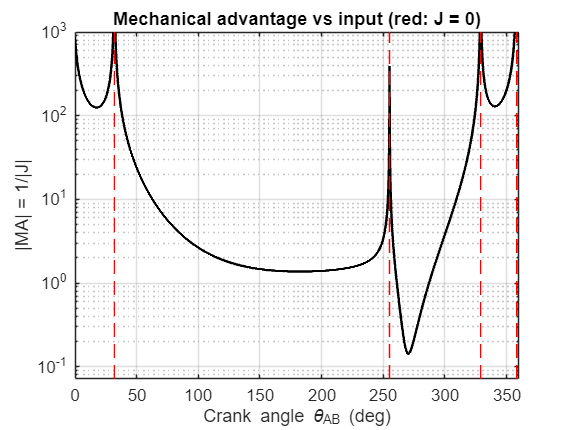


%% 8. Plotting the Mechanical Advantage v Input
figure;    % MA vs input
semilogy(thdeg, MA, 'k', 'LineWidth', 1.5); hold on; grid on;
ylim([0.5*MAmin 1e3]);  xlim([0 360]);
for a = eeAng
    plot([a a], [0.5*MAmin 1e3], 'r--');
end
xlabel('Crank angle \theta_{AB} (deg)'); ylabel('|MA| = 1/|J|');
title('Mechanical advantage vs input (red: J = 0)');


%% Forward kinematics (closed form, two circle intersections)
function q = fk(t, p)
B = p.L_AB*[cos(t); sin(t)];
C = circ(B, p.L_BC, p.rD, p.L_DC, p.sC);
thBC = atan2(C(2) - B(2), C(1) - B(1));
thDC = atan2(C(2) - p.rD(2), C(1) - p.rD(1));
M = C + p.L_CM*[cos(thBC + p.beta); sin(thBC + p.beta)];
N = circ(M, p.L_MN, p.rF, p.L_FN, p.sN);
thMN = atan2(N(2) - M(2), N(1) - M(1));
thFN = atan2(N(2) - p.rF(2), N(1) - p.rF(1));
q = [t; thBC; thDC; thMN; thFN];
end

function X = circ(P0, r0, P1, r1, s)
% Point at distance r0 from P0 and r1 from P1; s = +1/-1 picks the branch
d = norm(P1 - P0);
a = (r0^2 - r1^2 + d^2)/(2*d);
if r0^2 - a^2 < 0, error('Mechanism cannot assemble here: check dimensions'); end
e = (P1 - P0)/d;
X = P0 + a*e + s*sqrt(r0^2 - a^2)*[-e(2); e(1)];
end
